## Visualize Historical Portfolio VS Fitted Model

Copyright (c) 2018, MathWorks, Inc.

This file is used to visaulize the default rates grouped by year on book for both historical portfolio and fitted model.

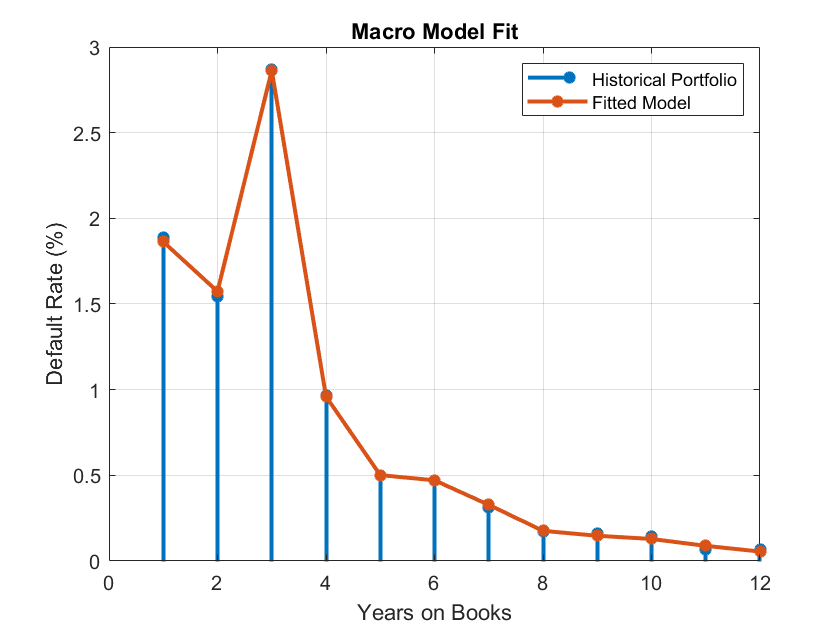

PredPD_historicalPortfolio = groupsummary(myLoanHistory,'YOB','mean','Default');
combinedHistory.PD = predict(myModel,combinedHistory(:,{'RiskLevel','YOB','DJX_Return','GDP'}));
PredPD_Model = groupsummary(combinedHistory,'YOB','mean','PD');

figure;
stem(PredPD_historicalPortfolio.YOB,PredPD_historicalPortfolio.mean_Default*100,'-*','linewidth',2);
hold on
plot(PredPD_Model.YOB,PredPD_Model.mean_PD*100,'-*','linewidth',2);
hold off
xlabel('Years on Books')
ylabel('Default Rate (%)')
legend('Historical Portfolio', 'Fitted Model')
title('Macro Model Fit')
grid on